# Comparing Ice Thickness in the past decade

The [Climate Data Store](https://cds.climate.copernicus.eu/) is a wealth of information about the Earth's past, present and future climate.  It is freely available and functions as a one-stop shop to explore climate data. There are hundreds of data sets associated with climate change.

[The sea ice thickness dataset](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice-thickness) provides monthly gridded data of sea ice thickness for the Arctic region based on satellite radar altimetry observations. Sea ice is an important component of our climate system and a sensitive indicator of climate change. Its presence or its retreat has a strong impact on air-sea interactions, the Earth’s energy budget as well as marine ecosystems. It is recognized by the Global Climate Observing System as an Essential Climate Variable. Sea ice thickness is one of the parameters commonly used to characterize sea ice, alongside sea ice concentration, sea ice edge, and sea ice type, also available in the Climate Data Store.

## Download and Extract the ice thickness data from Climate Data Store

Select the sea ice thickness dataset

datasetName = "satellite-sea-ice-thickness";

Select the data to download from the dataset (see [this webpage](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice-thickness?tab=form) for options).  This is a "MATLABized" version of the python structure that is generated in the API request.

datasetOptions.version = "1_0";
datasetOptions.variable = "all";
datasetOptions.satellite = "cryosat_2";
datasetOptions.cdr_type = ["cdr","icdr"];
datasetOptions.year = ["2011","2021"];
datasetOptions.month = "03";

Download the data from Climate Data Store using `climateDataStoreDownload`.  It is put in a directory called "satellite-sea-ice-thickness."

[downloadedFilePaths,citation] = climateDataStoreDownload(datasetName,datasetOptions);

2022-06-19 07:30:55,322 INFO Welcome to the CDS
2022-06-19 07:30:55,326 INFO Sending request to https://cds.climate.copernicus.eu/api/v2/resources/satellite-sea-ice-thickness
2022-06-19 07:30:55,681 INFO Downloading https://download-0002-clone.copernicus-climate.eu/cache-compute-0002/cache/data5/dataset-satellite-sea-ice-thickness-fd5f5f42-1856-41cc-ab13-145e53e4848e.zip to dataset-satellite-sea-ice-thickness-fd5f5f42-1856-41cc-ab13-145e53e4848e.zip (4.4M)
2022-06-19 07:30:57,214 INFO Download rate 2.8M/s


The function also returns the appropriate citation for the data

disp(citation)

Generated using Copernicus Climate Change Service information 2022


## Explore the ice thickness data

Look at the second file (March 2021) to get variable information

info = ncinfo(downloadedFilePaths(2));
info.Variables

ans = 1×11 struct array with fields:
    Name
    Dimensions
    Size
    Datatype
    Attributes
    ChunkSize
    FillValue
    DeflateLevel
    Shuffle


## Read and format ice thickness data from 2011 and 2021

Transform and load the latitude, longitude, and ice thickness.  

ice2011 = readSatelliteSeaIceThickness(downloadedFilePaths(1));
ice2021 = readSatelliteSeaIceThickness(downloadedFilePaths(2));
head(ice2021)

       time         lat       lon      thickness
    ___________    ______    ______    _________

    01-Mar-2011    50.127    145.99      0.1823 
    01-Mar-2011    50.055    145.26    0.030603 
    01-Mar-2011    50.387    145.35     0.38821 
    01-Mar-2011    50.251    145.08     0.36701 
    01-Mar-2011    50.583    145.16     0.24477 
    01-Mar-2011    51.051    145.52     0.37633 
    01-Mar-2011    50.779    144.97     0.33518 
    01-Mar-2011    51.781    146.45     0.57332 



## Visually compare March ice thickness in 2011 and 2021

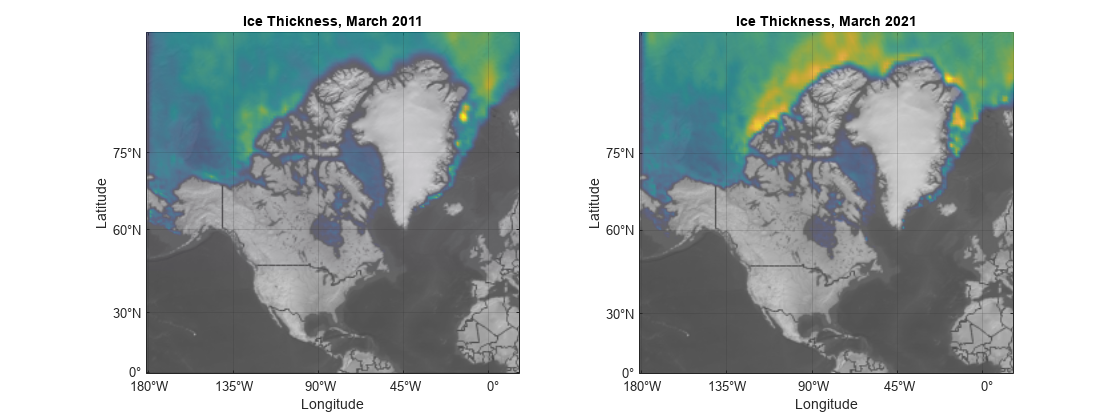

subplot(1,2,1)
geodensityplot(ice2011.lat,ice2011.lon,ice2011.thickness,"FaceColor","interp")
geolimits([23 85],[-181.4 16.4])
geobasemap("grayterrain")
title("Ice Thickness, March 2011")

subplot(1,2,2)
geodensityplot(ice2021.lat,ice2021.lon,ice2021.thickness,"FaceColor","interp")
geolimits([23 85],[-181.4 16.4])
geobasemap("grayterrain")
title("Ice Thickness, March 2021")
f = gcf;
f.Position(3) = f.Position(3)*2;

disp(citation)

Generated using Copernicus Climate Change Service information 2022


Clean up the downloaded files

[downloadDirectory,~,~] = fileparts(downloadedFilePaths(1));
rmdir(downloadDirectory,'s')

Copyright 2021-2022 The MathWorks, Inc.